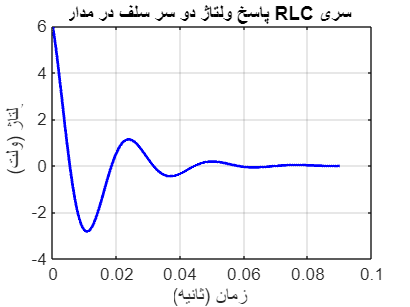

clc;
clear;
% سری
% پارامترهای مدار
R = 280;               % مقاومت (اهم)
L = 2;                 % سلف (هِنری)
C = 8e-6;              % خازن (فارد)
Vs = 30;               % منبع ولتاژ (ولت)
I0 = 0;                % جریان اولیه (آمپر)
V0_cap = 6;            % ولتاژ اولیه خازن (ولت)

% محاسبات اولیه
alpha = R / (2 * L);             % ثابت میرایی
omega_0 = 1 / sqrt(L * C);       % فرکانس طبیعی (رادیان بر ثانیه)
omega_d = sqrt(omega_0^2 - alpha^2); % فرکانس میرایی (رادیان بر ثانیه)

% ضرایب پاسخ گذرا
A = I0;
B = (V0_cap / L - alpha * A) / omega_d;

% زمان
t = linspace(0, 0.09, 1000); % بازه زمانی 0.01 ثانیه

% جریان در مدار
i_t = exp(-alpha * t) .* (A * cos(omega_d * t) + B * sin(omega_d * t));

% ولتاژ دو سر سلف
v_L = L * gradient(i_t, t);

% رسم نمودار
figure;
plot(t, v_L, 'b', 'LineWidth', 1.5);
title('پاسخ ولتاژ دو سر سلف در مدار RLC سری');
xlabel('زمان (ثانیه)');
ylabel('ولتاژ (ولت)');
grid on;


disp(omega_0)

   250




% نمایش فرمول روی نمودار

